# **SMDP Formulation of MVT**

## **Semi Markov Decision Process **

Here we consider the process of going in and learning the average reward rate of the environment as a SMDP. 

First we are going to get the motor costs out of the way. We are going to use the parameters from Shadmehr, Huang and Ahmed (2016) to represent the motor cost of travelling between patches. 

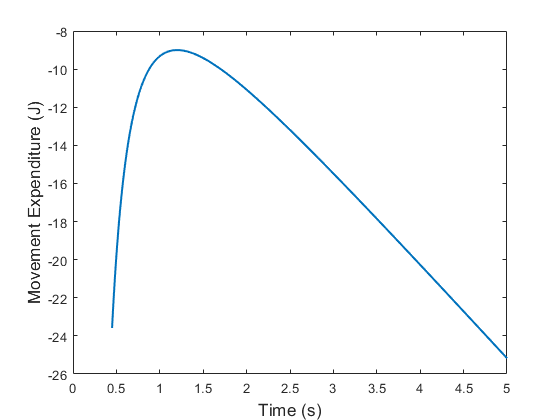

% parameters from the paper - global
a = 5;
b = 10;
j = 3;
i = 1.1; k=.7;
% equation for effort cost ( Shadmehr, Huang, Ahmed 2016)

u_m = @(m,d,t) -1*(a*t + b*(m^k)*(d^i)./(t.^(j-1)));

% Plot the effort cost wrt to time to illustrate what it looks like
d = 0.30;
m = 2;
tm = 0.45:0.01:5; % assume seconds

plot(tm, u_m(m,d,tm), 'LineWidth',1.5);
xlabel('Time (s)','FontSize',13)
ylabel('Movement Expenditure (J)','FontSize',13)

## Harvest function:

To implement as a SMDP, we need to compute the duration between every successive berry pop. 

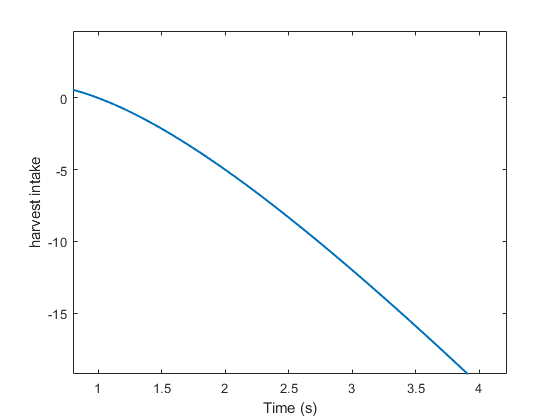

% Hyperbolic decay in berry rate

%max berries
alpha =  30;
beta = 0.5;
Fg = 10; % Force level required
u_h = @(th) alpha*(1 - 1./(1+ beta*th)) - Fg*th;

th = 0.:0.01:5;
plot(th, u_h(th),'LineWidth',1.5)
xlabel('Time (s)')
ylabel('harvest intake')

% Use a reward rate

dur = @(t) alpha*beta./((1+ beta*t).^2 )

dur = function_handle with value:
    @(t)alpha*beta./((1+beta*t).^2)


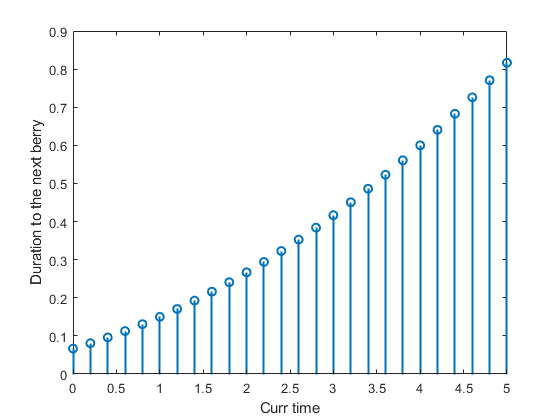

t = 0.:0.2:5;
stem(t,1./dur(t),'Linewidth',1.5)
xlabel('Curr time')
ylabel('Duration to the next berry')


% xlim([0.0 5.11])
% ylim([0.0 0.1002])

The max number of berries is super high, but we get a reasonable looking harvest function now. Now use the average reward Bellman Equation for SMDP to solve for this using relative value iteration. 

SMDP asynchronous value iteration algorithm based on Mahadevan (1994) for MDPs  - attempt to extend to SMDP

% % Travel Durations are constant for now
% m=2;
% ts=[1.5, 2.5];
% clf
% d=0.3;
% actions = [0,1];
% t_max = 30*60;
% states = 0:1:50;
%
% t_states = 0:0.1:t_max;
% p=1;
% acts =[];
% states_act=[];
% pho_vec = [];
% f_rate_vec = [];
%
% for tm=ts
%     figure
%     x = 0; % initialized state - 0 berries to begin with
%     t_cur = 0.001;
%     t_patch = 0;
%     Kt = 0;
%     pho = 20;
%     val = zeros(size(states)); % relative value function
%     val_next = val;
%     k = 0; % iteration count
%
%     while t_cur < t_max
%         cur_val = zeros(1,length(actions));
%         r_vec = zeros(1,length(actions));
%         for a= actions
%             if a
%                 r_vec(a+1) = u_m(m,d,tm);
%             else
%                 %                 berry_gap =1/dur(t_cur);
%                 r_vec(a+1) = u_h(t_patch);
%             end
%
%             y = (1-a)*(x+1);
%             v_ix = (y==states);
%             val_c = ( r_vec(a+1) + val(v_ix) );
%
%             if isempty(val_c)
%                 break;
%             end
%             cur_val(a+1) = val_c;
%         end
%
%         [~, a] = max(cur_val);
%
%         %         if a ==1
%         %             a= double(binornd(1, 0.05));
%         %         else
%         %             a = double(binornd(1,0.95));
%         %         end
%
% %         a = a-1;
%
%         if a
%             t_add = tm;
%         else
%             t_add = 1/dur(t_cur);
%         end
%
%         x_next = (1-a)*(x + 1) ;%+ a*x;
%
%         if isempty(find(x==states))
%             break
%         end
%
%         val_next(x==states) = cur_val(a+1) - pho*t_add;
%         Kt_next = Kt + r_vec(a+1);
%         acts(end+1) = a;
%         states_act(end+1)=x;
%
%
%         figure(1)
%         subplot(2,3,p)
%         plot(states,val);
%         ylabel('Value Function')
%         xlabel('State')
%         subplot(2,3,p+1)
%         plot(states_act,'b')
%         ylabel('State ( Reward)')
%         subplot(2,3,p+2)
%         plot(acts,'r*')
%         ylabel('Action')
%
%         % Relation between current pho and rate at exit
%         pho_vec(end+1) = pho;
%         f_rate_vec(end+1) = dur(t_patch);
%
%         drawnow
%         Kt = Kt_next;
%         x =x_next;
%         val = val_next;
%         t_cur = t_cur + t_add;
%         t_patch = t_patch + (1-a)*t_add;
%         pho = Kt_next / t_cur;
%         k = k+1;
%     end
%     p = p+3;
%     figure(2)
%
%     scatter(f_rate_vec,pho_vec)
%     hold on
%
%     pho
% end
% figure(2)
% xlabel('Average Capture Rate')
% ylabel('Harvest rate in patch')
% legend('tm=1.5','tm=2.5');
%


Let us simulate constantino and Daw, 

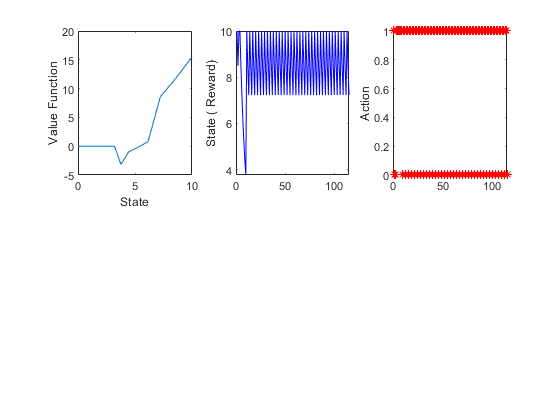

S0 = 10; % initial state of a new tree
actions = [0,1]; % 0- travel; 1- harvest

h = 4.5; % fixed duration per harvest action
ts = [6]; % long and short travel durations

kappa = 0.85;
sigma_r = 0.18;

% Implementing relative value iteration for the average value MDP

states = [];
p=1;
acts =[];
states_act=[];
pho_vec = [];
f_rate_vec = [];

s_cur = S0;

while s_cur >= 0.00001
    
    states = [states, s_cur];
    s_cur = kappa*s_cur;
end
% keyboard;
states = [states,0];

val = zeros(size(states)); % relative value function
val_next = val;
k = 0; % iteration count

alpha = 0.6;
beta = 1;
c= 2;

pho = 0; % initialized

% Simulating the asynchronous adaptive control

t_max = 15*60; % 14 minutes

reward = @(s, a )( a* normrnd(s, sigma_r) );
exp_reward = @(s,a)( a * nansum( norminv(0:0.001:1, s, sigma_r).* ...
    (normpdf(norminv(0:0.001:1,s, sigma_r), s, sigma_r)./...
    sum(normpdf(norminv(0:0.001:1,s, sigma_r), s, sigma_r)) )) );


for d = ts
    
    x = S0; % initialized state
    t_cur = 0;
    Kt = 0;
    while t_cur < t_max
        
        cur_val = zeros(1,length(actions));
        r_vec = zeros(1,length(actions));
        for a= actions
            
            r =  exp_reward(x, a);
            r_vec(a+1) = r;
            y = a * kappa* x + (1-a)*S0;
            % if a = 0 , reset state to S0, else decrement tree bounty
            
            v_ix = (y==states);
            val_c = ( r + val(v_ix) );
            if isempty(val_c)
                break;
            end
            cur_val(a+1) = val_c;
        end
        [~, a] = max(cur_val);
%         
%         if a ==1
%             a= double(binornd(1, 0.05));
%         else
%             a = double(binornd(1,0.95));
%         end
        a = a-1;
        
        acts(end+1) = a;
        states_act(end+1)=x;
        
        
        figure(1)
        subplot(2,3,p)
        plot(states,val);
        ylabel('Value Function')
        xlabel('State')
        subplot(2,3,p+1)
        plot(states_act,'b')
        ylabel('State ( Reward)')
        subplot(2,3,p+2)
        plot(acts,'r*')
        ylabel('Action')
        
        % Relation between current pho and rate at exit
        pho_vec(end+1) = pho;
        f_rate_vec(end+1) = kappa*x/ h;
        
        drawnow
        
        x_next = a * kappa* x + (1-a)*S0;
        if isempty(find(x==states))
            break
        end
        val_next(x==states) = cur_val(a+1) - pho*(a*h + (1-a)*d);
        Kt_next = Kt + r_vec(a+1);
        
        Kt = Kt_next;
        x =x_next;
        val = val_next;
        t_cur = t_cur + (a*h + (1-a)*d);
        pho = Kt_next / t_cur;
        k = k+1;
        
    end
    p = p+3;
    %     figure(2)
    %
    %     scatter(f_rate_vec,pho_vec)
    %     hold on
    %
    pho
end

figure(2)
xlabel('Average Capture Rate')
ylabel('Harvest rate in patch')
legend('tm=6','tm=9');
keyboard


After  training the average rate differential bellaman equation let's simulate what the subject would do.

% p=1;
% acts =[];
% states_act=[];
% pho_vec = [];
% f_rate_vec = [];
% 
% for d = ts
%     
%     x = S0; % initialized state
%     t_cur = 0;
%     Kt = 0;
%     while t_cur < t_max
%         
%         [~, a] = max(cur_val);
%         if a ==1
%             a= double(binornd(1, 0.05));
%         else
%             a = double(binornd(1,0.95));
%         end
% %         a = a-1;
%         
%         acts(end+1) = a;
%         states_act(end+1)=x;
%         
%         
%         figure(1)
%         subplot(2,3,p)
%         plot(states,val);
%         ylabel('Value Function')
%         xlabel('State')
%         subplot(2,3,p+1)
%         plot(states_act,'b')
%         ylabel('State ( Reward)')
%         subplot(2,3,p+2)
%         plot(acts,'r*')
%         ylabel('Action')
%         
%         % Relation between current pho and rate at exit
%         pho_vec(end+1) = pho;
%         f_rate_vec(end+1) = kappa*x/ h;
%         
%         drawnow
%         x = a * kappa* x + (1-a)*S0;
%         t_cur = t_cur + (a*h + (1-a)*d);
%     end
%     p = p+3;
%     figure(2)
%     
%     scatter(f_rate_vec,pho_vec)
%     hold on
%     
%     pho
% end
% keyboard
% figure(2)
% xlabel('Average Capture Rate')
% ylabel('Harvest rate in patch')
% legend('tm=6','tm=9');
